## Spectrogram Generation 

### Control Signals

% Locate the TVALID and TLAST control signals of the FFT
fft_out_tvalid = out.TVALID

fft_out_tvalid =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


find(fft_out_tvalid == 1, 1)

ans = 4237

fft_out_tlast = out.TLAST

fft_out_tlast =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


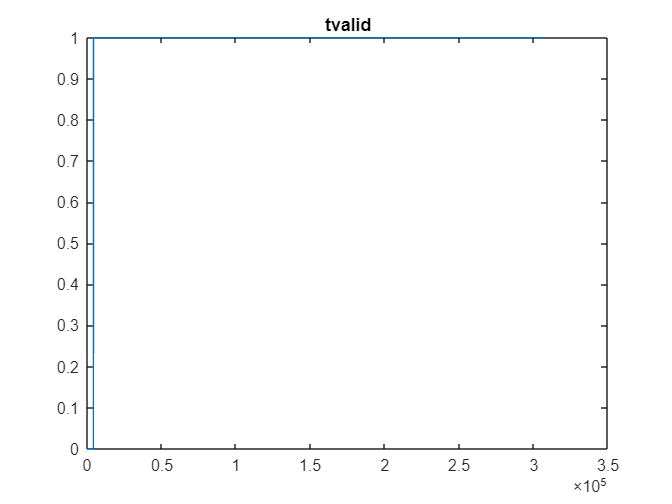

plot(1:length(fft_out_tvalid),fft_out_tvalid)
title('tvalid')

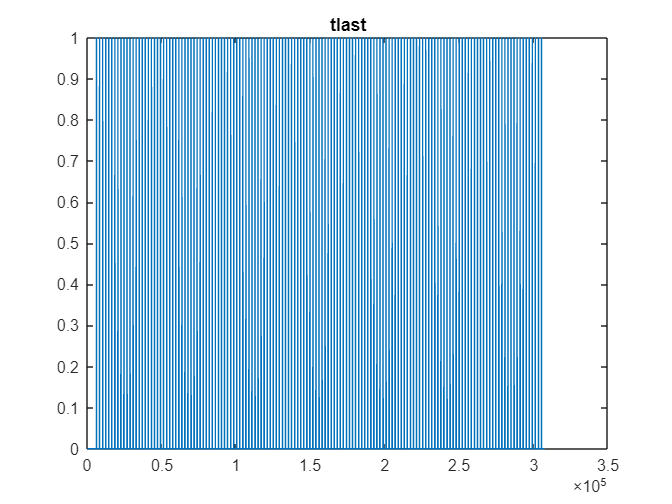

plot(1:length(fft_out_tlast),fft_out_tlast)
title('tlast')


% Set TLAST signal from first TVALID to keep it with data output
fft_out_tlast = fft_out_tlast(find(fft_out_tvalid == 1, 1):end)

fft_out_tlast =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


find(fft_out_tlast,1,'first')

ans = 2048

### HDL block floating point 

% Locate the FFT data output
fft_out_log_ = out.FFT_out_log

fft_out_log_ =      0
     0
     0
     0
  -512
  -512
  -512
  -512
  -512
  -512


% Only keep the valid samples
fft_out_log = fft_out_log_(find(fft_out_tvalid == 1, 1):end)

fft_out_log =  -152.3184
 -151.6747
 -149.4918
 -151.6747
 -149.4918
 -151.6747
 -149.4918
 -151.6747
 -149.4918
 -151.6747


% Zero-pad if neccessary to ensure # samples is an integer multiple of the
% window size (required for easier spectrogram plotting)
fft_length_before_zero_padding = (ceil(length(fft_out_log)/N))

fft_length_before_zero_padding = 148


% Set the zero-padded values to the minimum value of the valid samples
fft_out_log(length(fft_out_log)+1:fft_length_before_zero_padding*N)=min(fft_out_log)

fft_out_log =  -152.3184
 -151.6747
 -149.4918
 -151.6747
 -149.4918
 -151.6747
 -149.4918
 -151.6747
 -149.4918
 -151.6747



% Determine key parameters
Total_Num_Samples = length(fft_out_log)

Total_Num_Samples = 303104

Num_Segments = Total_Num_Samples/N

Num_Segments = 148


% Create the frequency and time axis for both spectrograms
f_axis_1N = (n/N*fs)/1e6; % From 0 -> fs
f_axis_1N_ = (-N/2:N/2-1)*(fs/N)/1e6; % From -fs/2 -> fs/2 (combined with fftshift for centring DC - as high f is just a spectral replication of -ve f)
t_axis_1N = linspace(0,Total_Num_Samples/fs,Num_Segments)

t_axis_1N =          0    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0006    0.0006    0.0007    0.0007    0.0007    0.0008    0.0008    0.0008    0.0009    0.0009    0.0009    0.0010    0.0010    0.0010    0.0011    0.0011    0.0011    0.0012    0.0012    0.0012    0.0013    0.0013    0.0013    0.0014    0.0014    0.0014    0.0014    0.0015    0.0015    0.0015    0.0016


t_axis_1N = 1e3.*t_axis_1N

t_axis_1N =          0    0.0322    0.0644    0.0967    0.1289    0.1611    0.1933    0.2255    0.2577    0.2900    0.3222    0.3544    0.3866    0.4188    0.4510    0.4833    0.5155    0.5477    0.5799    0.6121    0.6444    0.6766    0.7088    0.7410    0.7732    0.8054    0.8377    0.8699    0.9021    0.9343    0.9665    0.9987    1.0310    1.0632    1.0954    1.1276    1.1598    1.1921    1.2243    1.2565    1.2887    1.3209    1.3531    1.3854    1.4176    1.4498    1.4820    1.5142    1.5464    1.5787


f_axis = repmat(f_axis_1N,1,Num_Segments)

f_axis =          0    0.0312    0.0625    0.0938    0.1250    0.1562    0.1875    0.2188    0.2500    0.2812    0.3125    0.3438    0.3750    0.4062    0.4375    0.4688    0.5000    0.5312    0.5625    0.5938    0.6250    0.6562    0.6875    0.7188    0.7500    0.7812    0.8125    0.8438    0.8750    0.9062    0.9375    0.9688    1.0000    1.0312    1.0625    1.0938    1.1250    1.1562    1.1875    1.2188    1.2500    1.2812    1.3125    1.3438    1.3750    1.4062    1.4375    1.4688    1.5000    1.5312


f_axis_ = repmat(f_axis_1N_,1,Num_Segments)

f_axis_ =   -32.0000  -31.9688  -31.9375  -31.9062  -31.8750  -31.8438  -31.8125  -31.7812  -31.7500  -31.7188  -31.6875  -31.6562  -31.6250  -31.5938  -31.5625  -31.5312  -31.5000  -31.4688  -31.4375  -31.4062  -31.3750  -31.3438  -31.3125  -31.2812  -31.2500  -31.2188  -31.1875  -31.1562  -31.1250  -31.0938  -31.0625  -31.0312  -31.0000  -30.9688  -30.9375  -30.9062  -30.8750  -30.8438  -30.8125  -30.7812  -30.7500  -30.7188  -30.6875  -30.6562  -30.6250  -30.5938  -30.5625  -30.5312  -30.5000  -30.4688


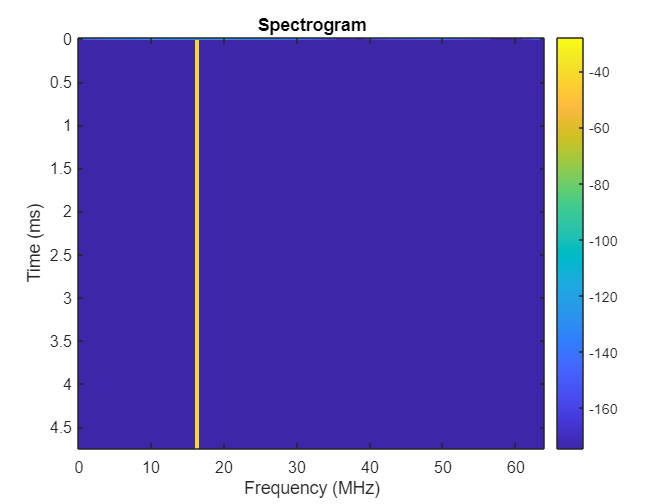


% Fill in the arrays to plot the spectrograms
for i=1:Num_Segments
    index = (i-1)*N+1 : i*N;
    t_axis(index) = t_axis_1N(i);   
    Data(i,:) = fft_out_log(index);
    Data_shift(i,:) = fftshift(Data(i,:));
end

% Plot spectrograms 
figure;
imagesc(f_axis,t_axis,Data)
title('Spectrogram')
xlabel('Frequency (MHz)')
ylabel('Time (ms)')
colorbar

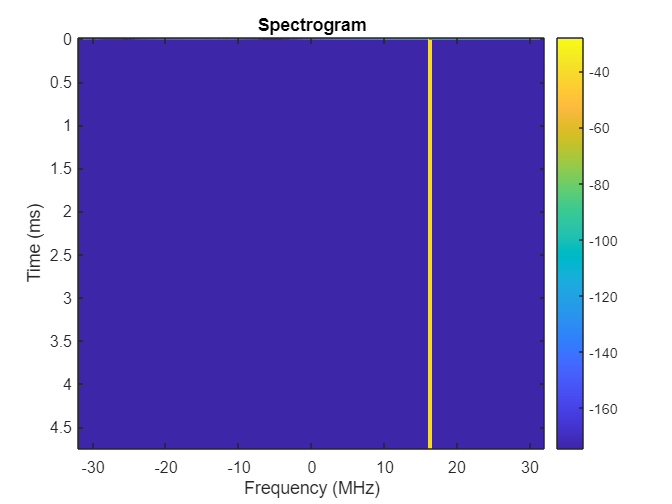

figure;
imagesc(f_axis_,t_axis,Data_shift)
title('Spectrogram')
xlabel('Frequency (MHz)')
ylabel('Time (ms)')
colorbar


% Plot 1st spectrum 
first_spectrum = fft_out_log(1:find(fft_out_tlast,1,'first')) % Or just Data(1,:)

first_spectrum =  -152.3184
 -151.6747
 -149.4918
 -151.6747
 -149.4918
 -151.6747
 -149.4918
 -151.6747
 -149.4918
 -151.6747


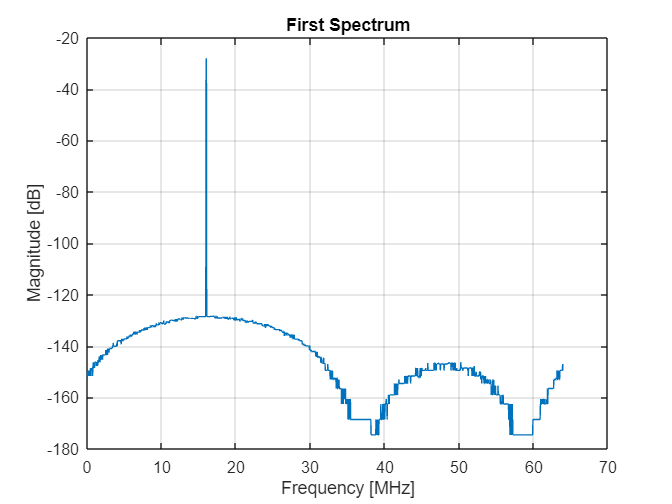

figure;
plot(f_axis_1N,first_spectrum);
xlabel('Frequency [MHz]');
ylabel('Magnitude [dB]');
title('First Spectrum');
grid on;